clear all
close all
clc

% set constants
cp_air = 1000; % [J/kg K]  Specific Heat Coefficient of Air at constant pressure
mdot = 10.4333;   % [kg/s]    Air mass flow
g_a = 1.4;    % [-]       Specific heat ratio
alt = 35000;
alt = alt * 0.3048;
M = 0.78;
R_a = cp_air * ((g_a-1)/g_a);

% choose the parameters:
Rm = 0.27;     % [m]       Mean Radius of the Compressor
U = 450;      % [m/s]     Tangential Speed of the Rotor
Omega = U/(2*pi*Rm) * 60;      % [rpm]   Rotations per minute

% choose the coefficients of the compressor
% phi = 0.3;    % [-]       Flow Coefficient
% psi = 0.25;    % [-]       Work Coefficient
R = 0.5;      % [-]       Reaction Ratio
h = 0.2;      % [-]       Ratio between the span of the first rotor and the mean radius Rm
span0 = Rm*h;                  % [m]       Span of the first rotor
Area0 = 2*pi*Rm*span0;         % [m^2]     Area of the first rotor
c0 = mdot/Area0;

Compute the number of stages and recompute U, compute cm:

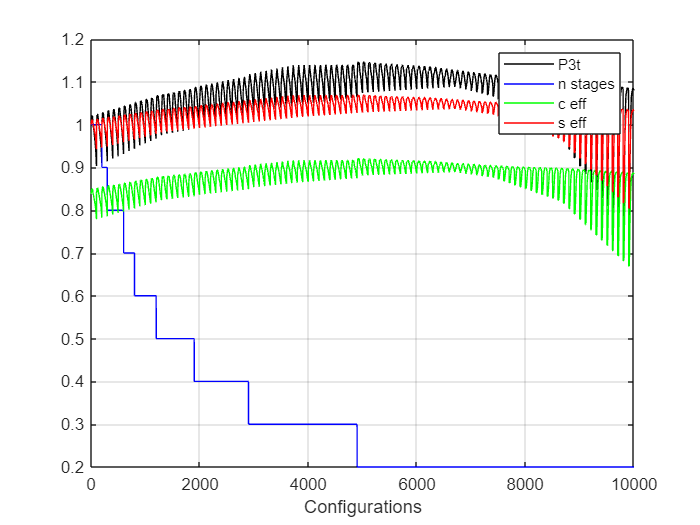

w = 199313.9750017056;        % [W/(kg/s)] Specific work required by the Compressor (from 3rd Deliverable)

dat = importdata("Smith_Chart_file.txt");

[P0s, T0s, rho0s] = ISA(alt);
P0 = P0s*(1 + ((g_a-1)/2) * M^2)^(g_a/(g_a-1));
T0 = T0s*(1 + ((g_a-1)/2) * M^2);
rho0 = P0 / (R_a * T0);

list_nstages = zeros(1, length(dat));
list_temperatures = zeros(1, length(dat));
list_pressures = zeros(1, length(dat));
list_efficiencies = zeros(1, length(dat));
ideal = 0;

for i = 1:length(dat)
    phi = dat(i,1);
    psi = dat(i,2);
    eta_stage = dat(i,3);
    U = 450;

    n_stage_pure = w/(psi*(U^2));
    n_stages = ceil(w/(psi*U^2));    % [-] Number of stages is computed and made nearest integer
    list_nstages(i) = n_stages;
    w_stages = w/n_stages;           % [W] Work per stage
    U = sqrt(w_stages/psi);          % [m/s] We recompute U to fit the exact number of stages
    cm = phi*U;                      % [m/s] Meridional velocity is computed
    alpha1 = atan((R-1+psi/2)/(-phi));        % [rad]  angle α1
    beta2 = - alpha1;                         % [rad]  angle β2
    beta1 = atan(tan(alpha1) - 1/phi);        % [rad]  angle β1
    alpha2 = atan(tan(beta2) + 1/phi);        % [rad]  angle α2 
    c1 = cm / (cos(alpha1));                  % [m/s]  velocity c1
    w1 = sqrt((U - c1*sin(alpha1))^2 + cm^2); % [m/s]  velocity w2
    c2 = w1;                                  % [m/s]  velocity c2
    w2 = c1;                                  % [m/s]  velocity w2
    T_in = zeros(1, n_stages);      % [K]   Start of stage temperatures
    T_in_s = zeros(1, n_stages); 
    T_out = zeros(1, n_stages);     % [K]   End of stage temperatures
    T_out_s = zeros(1, n_stages);
    p_in = zeros(1, n_stages);      % [Pa]  Start of stage pressures
    p_in_s = zeros(1, n_stages); 
    p_out = zeros(1, n_stages);     % [Pa]  End of stage pressures
    p_out_s = zeros(1, n_stages);
    pr = zeros(1, n_stages);        % [-]   Stage pressure ratios
    rho_in = zeros(n_stages, 1);    % [kg/m^3] Start of stage density
    rho_in_s = zeros(n_stages, 1);
    rho_out = zeros(n_stages, 1);   % [kg/m^3] End of stage density
    rho_out_s = zeros(n_stages, 1);
    A_in = zeros(n_stages, 1);      % [m^2] Start of stage area
    A_out = zeros(n_stages, 1);     % [m^2] End of stage area
    span_in = zeros(n_stages, 1);   % [m] Start of stage blade span
    span_out = zeros(n_stages, 1);  % [m] End of stage blade span
    
    
    T_in(1) = T0;                       % [K]           Temperature at the first stage
    T_in_s(1) = T0s;
    p_in(1) = P0;                       % [pa]          Pressure at the first stage
    p_in_s(1) = P0s; 
    rho_in(1) = rho0;  % [kg/m^3]      Density at the first stage
    rho_in_s(1) = rho0s;
    A_in(1) = mdot / (rho_in_s(1) * cm);      % [m^2]         Area of the first stage
    span_in(1) = A_in(1) / (2*pi*Rm);       % [m]           Span of the first stage
    
    for stage = 1:n_stages  % loop to compute parameters of all stages
        T_out(stage) = T_in(stage) + w_stages/(cp_air);
        T_in(stage+1) = T_out(stage);
        
        T_out_s(stage) = T_out(stage) - (c1^2)/(2*cp_air);
        T_in_s(stage+1) = T_out_s(stage);
        
        pr(stage) = (eta_stage*((T_out(stage)/T_in(stage)) - 1) + 1)^(g_a/(g_a-1));
        p_out(stage) = p_in(stage)*pr(stage);
        p_in(stage+1) = p_out(stage);
        
        p_out_s(stage) = p_out(stage)/(T_out(stage)/T_out_s(stage))^(g_a/(g_a-1));
        p_in_s(stage+1) = p_out_s(stage);
        
        rho_out(stage) = p_out(stage) / (R_a * T_out(stage));
        rho_in(stage+1) = rho_out(stage);
        
        rho_out_s(stage) = p_out_s(stage) / (R_a * T_out_s(stage));
        rho_in_s(stage+1) = rho_out_s(stage);

        A_out(stage) = mdot / (rho_out_s(stage) * cm);
        A_in(stage+1) = A_out(stage);
        
        span_out(stage) = A_out(stage) / (2*pi*Rm);
        span_in(stage+1) = span_out(stage);
    end
       
    list_temperatures(i) = T_out(end);
    list_pressures(i) = p_out(end);
    list_temperatures_s(i) = T_out_s(end);
    list_pressures_s(i) = p_out_s(end);
    pr_total = prod(pr);                                                    % [-]  Compressor Overall Pressure Ratio
    eta_total = (pr_total^((g_a-1)/g_a) - 1) / ((T_out(end)/T_in(1)) - 1);  % [-]  Efficiency of the entire compressor

    list_efficiencies(i) = eta_total;
    
    tolerance = 0.4;    
    tolerance2 = 1;
    target_pr = 6.8224;
    target_n_stages = 1;
    cpmax = 0.43;

    if ((pr_total <= target_pr+tolerance) && (pr_total >= target_pr-tolerance) && (cos(beta2)<cos(beta1)/sqrt(1-cpmax)) && (cos(alpha1 )<cos(alpha2 )/sqrt(1-cpmax)) )
        check(i) = true;
        
    else 
        check(i) = false;
    end

end
figure(1)
plot(list_pressures/list_pressures(1),'black')
hold on
plot(list_nstages/list_nstages(1),'blue')
hold on
plot(list_efficiencies,'green')
hold on
plot(dat(:,3)/dat(1,3),'red')
legend("P3t", "n stages", "c eff", "s eff")
grid on
xlabel("Configurations")

hold off

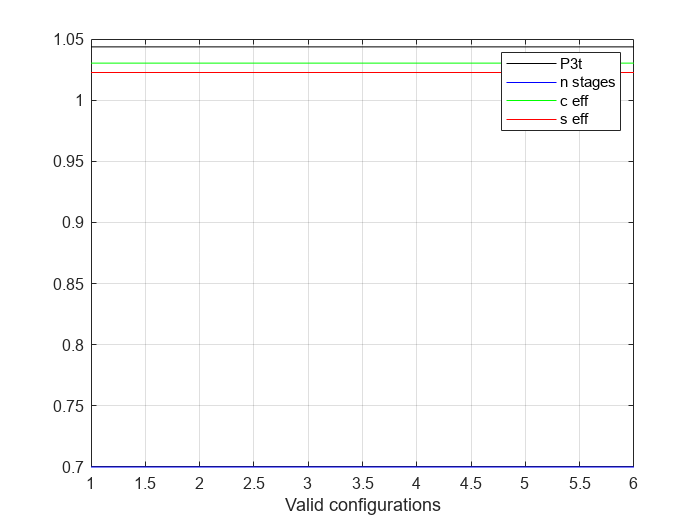

figure(2)
plot(list_pressures(check)/list_pressures(1),'black')
hold on
plot(list_nstages(check)/list_nstages(1),'blue')
hold on
plot(list_efficiencies(check)/list_efficiencies(1),'green')
hold on
plot(dat(check,3)/dat(1,3),'red')
hold off
legend("P3t", "n stages", "c eff", "s eff")
xlabel("Valid configurations")
grid on

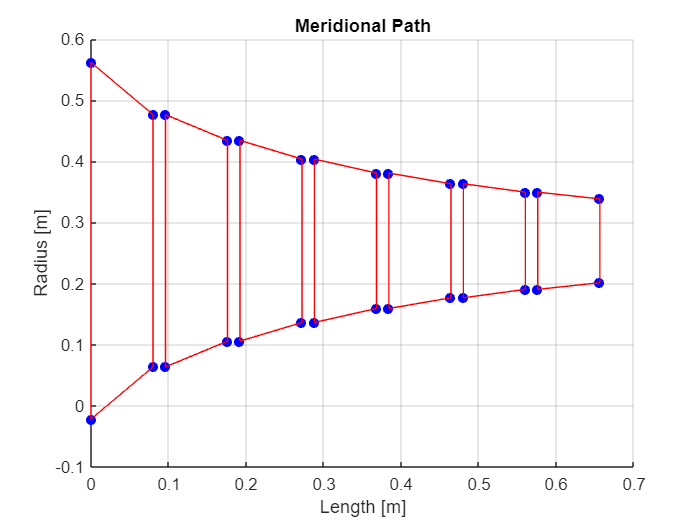

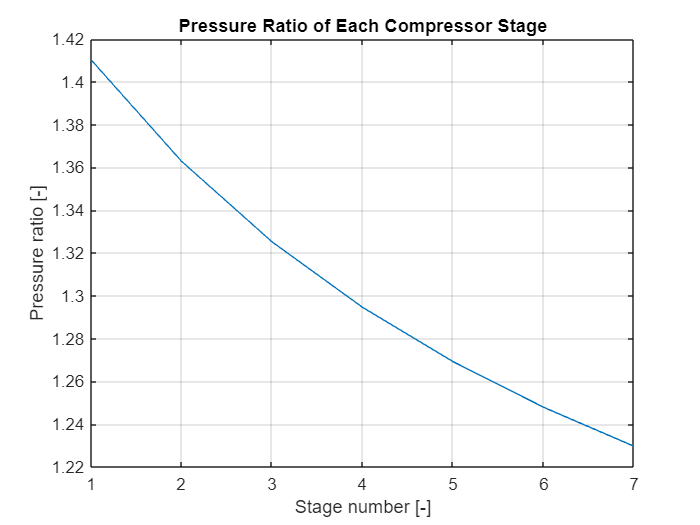

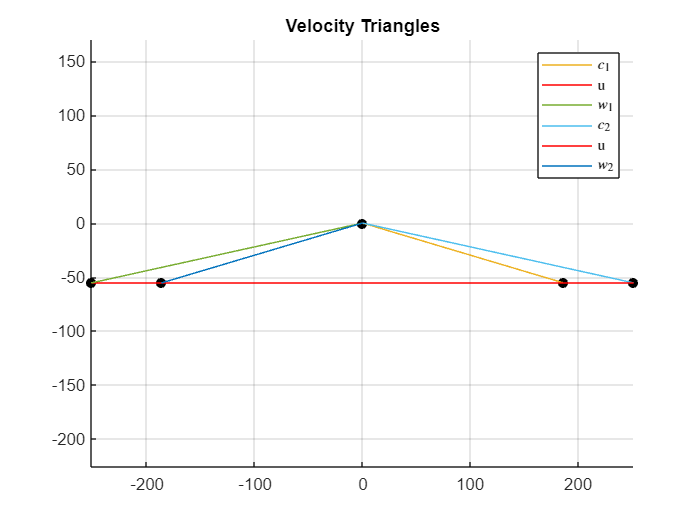

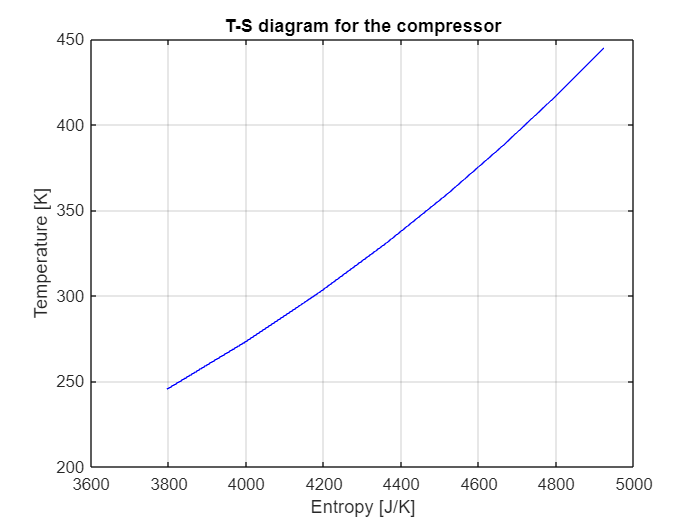

     Variable     after stage 0    after stage 1    after stage 2    after stage 3    after stage 4    after stage 5    after stage 6    after stage 7
    __________    _____________    _____________    _____________    _____________    _____________    _____________    _____________    _____________

    "p/p_t0"            1             1.6408           2.2914           3.0981           4.0787           5.2513            6.634           8.2452    
    "p_t/p_t0"          1             1.4103           1.9221           2.5472           3.2977           4.1856           5.2233           6.4231    
    "T_t/T_t0"          1              1.116            1.232            1.348           

n_stages = 7

pr_total = 6.4231

eta_total = 0.8636

phi = 0.1268

psi = 0.1485

U = 437.9036

Omega = 1.5488e+04

ans = 0.1163

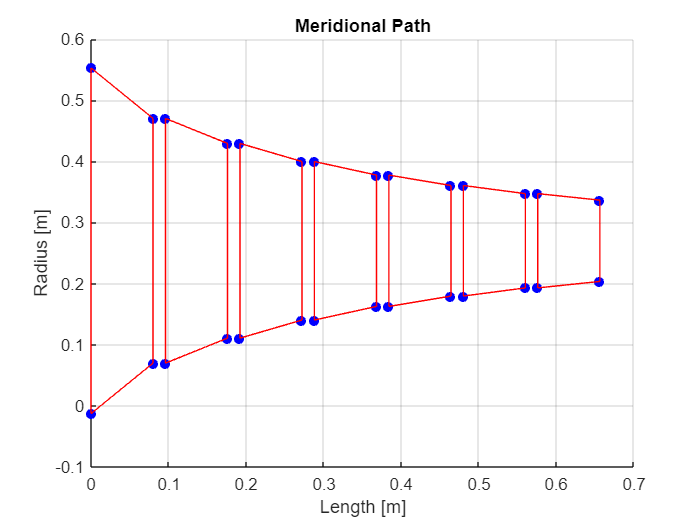

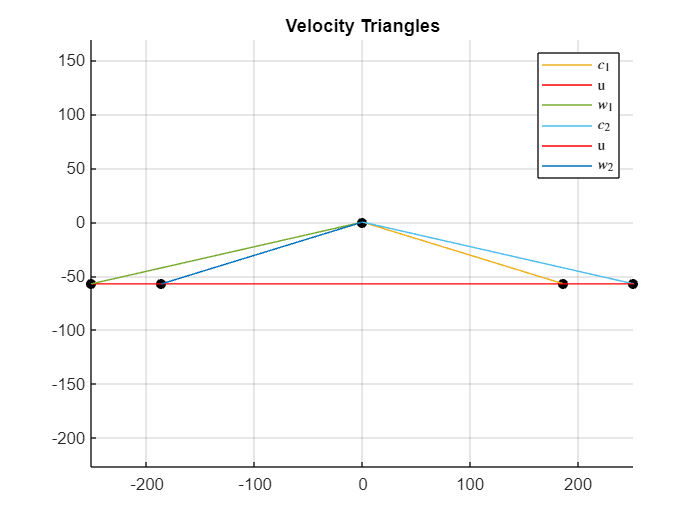

     Variable     after stage 0    after stage 1    after stage 2    after stage 3    after stage 4    after stage 5    after stage 6    after stage 7
    __________    _____________    _____________    _____________    _____________    _____________    _____________    _____________    _____________

    "p/p_t0"            1             1.6385           2.2885           3.0946           4.0745           5.2463           6.6282           8.2385    
    "p_t/p_t0"          1             1.4103           1.9221           2.5472           3.2977           4.1856           5.2233           6.4231    
    "T_t/T_t0"          1              1.116            1.232            1.348           

n_stages = 7

pr_total = 6.4231

eta_total = 0.8636

phi = 0.1308

psi = 0.1485

U = 437.9036

Omega = 1.5488e+04

ans = 0.1128

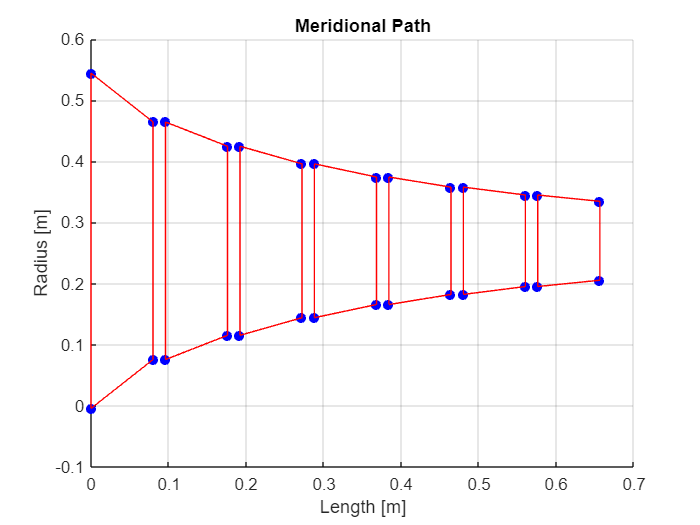

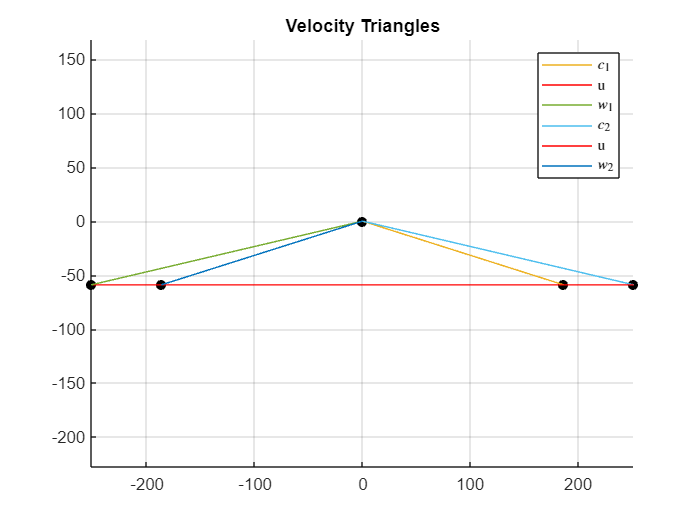

     Variable     after stage 0    after stage 1    after stage 2    after stage 3    after stage 4    after stage 5    after stage 6    after stage 7
    __________    _____________    _____________    _____________    _____________    _____________    _____________    _____________    _____________

    "p/p_t0"            1             1.6362           2.2856            3.091           4.0702           5.2412           6.6222           8.2315    
    "p_t/p_t0"          1             1.4103           1.9221           2.5472           3.2977           4.1856           5.2233           6.4231    
    "T_t/T_t0"          1              1.116            1.232            1.348           

n_stages = 7

pr_total = 6.4231

eta_total = 0.8636

phi = 0.1348

psi = 0.1485

U = 437.9036

Omega = 1.5488e+04

ans = 0.1094

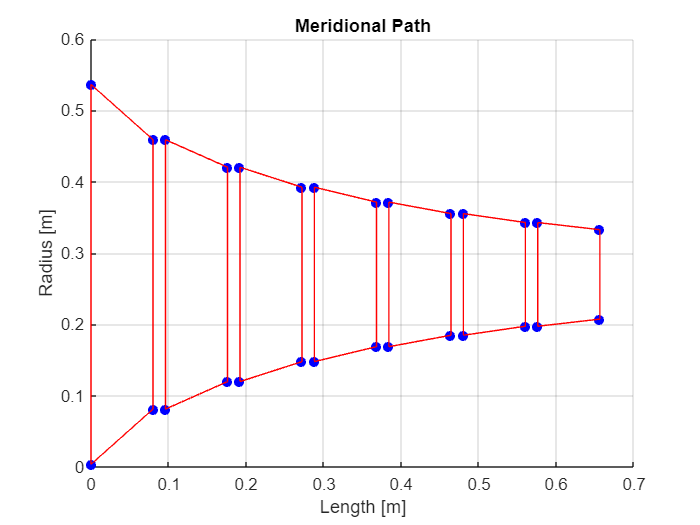

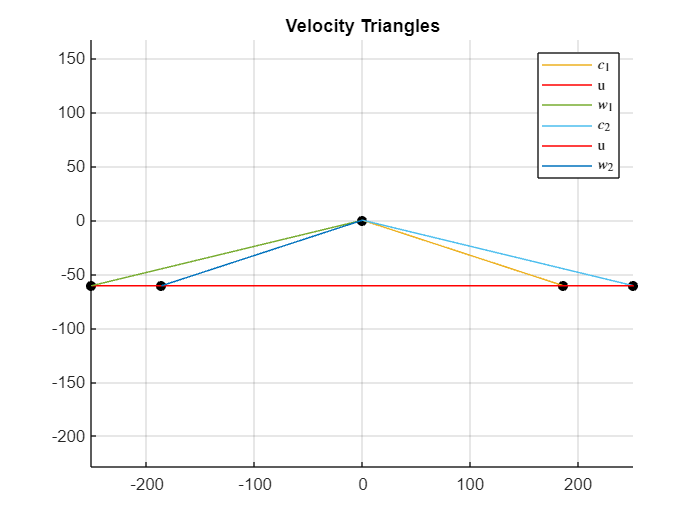

     Variable     after stage 0    after stage 1    after stage 2    after stage 3    after stage 4    after stage 5    after stage 6    after stage 7
    __________    _____________    _____________    _____________    _____________    _____________    _____________    _____________    _____________

    "p/p_t0"            1             1.6338           2.2826           3.0873           4.0658            5.236            6.616           8.2243    
    "p_t/p_t0"          1             1.4103           1.9221           2.5472           3.2977           4.1856           5.2233           6.4231    
    "T_t/T_t0"          1              1.116            1.232            1.348           

n_stages = 7

pr_total = 6.4231

eta_total = 0.8636

phi = 0.1389

psi = 0.1485

U = 437.9036

Omega = 1.5488e+04

ans = 0.1063

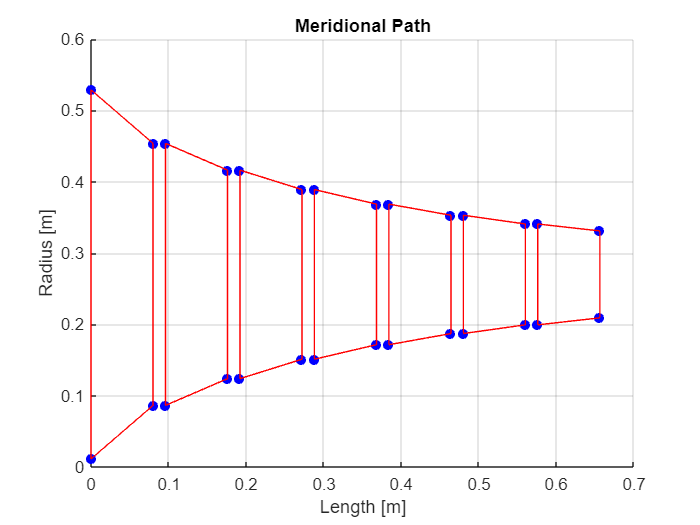

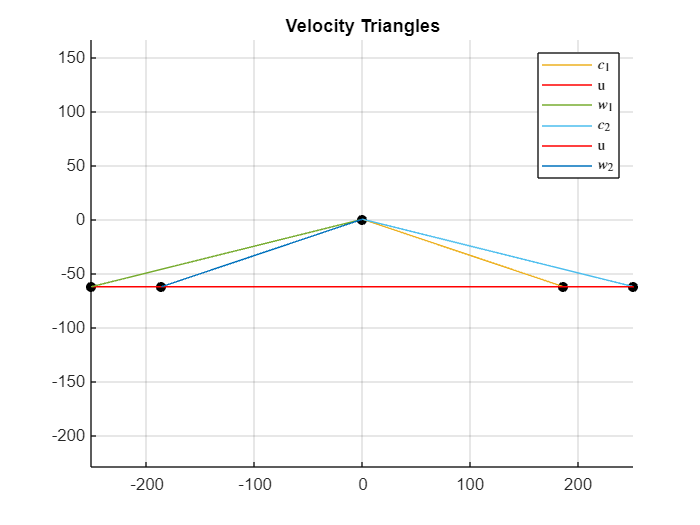

     Variable     after stage 0    after stage 1    after stage 2    after stage 3    after stage 4    after stage 5    after stage 6    after stage 7
    __________    _____________    _____________    _____________    _____________    _____________    _____________    _____________    _____________

    "p/p_t0"            1             1.6314           2.2795           3.0836           4.0612           5.2305           6.6097           8.2169    
    "p_t/p_t0"          1             1.4103           1.9221           2.5472           3.2977           4.1856           5.2233           6.4231    
    "T_t/T_t0"          1              1.116            1.232            1.348           

n_stages = 7

pr_total = 6.4231

eta_total = 0.8636

phi = 0.1429

psi = 0.1485

U = 437.9036

Omega = 1.5488e+04

ans = 0.1034

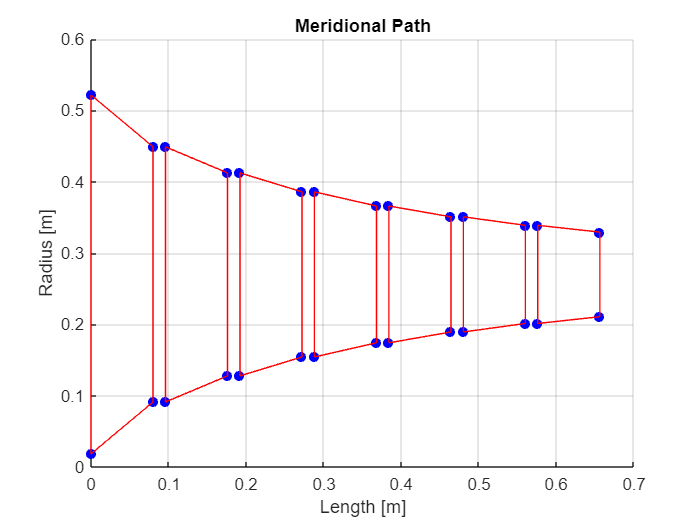

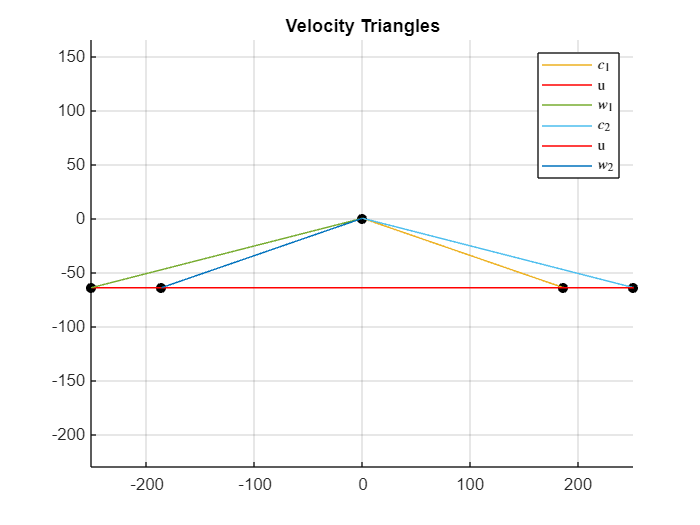

     Variable     after stage 0    after stage 1    after stage 2    after stage 3    after stage 4    after stage 5    after stage 6    after stage 7
    __________    _____________    _____________    _____________    _____________    _____________    _____________    _____________    _____________

    "p/p_t0"            1             1.6289           2.2764           3.0797           4.0565           5.2249           6.6031           8.2094    
    "p_t/p_t0"          1             1.4103           1.9221           2.5472           3.2977           4.1856           5.2233           6.4231    
    "T_t/T_t0"          1              1.116            1.232            1.348           

n_stages = 7

pr_total = 6.4231

eta_total = 0.8636

phi = 0.1470

psi = 0.1485

U = 437.9036

Omega = 1.5488e+04

ans = 0.1006

idx = 1;
nf = 3;

for n = 1:length(check)

    if check(n) == 0
        continue
    end
    phi = dat(n,1);
    psi = dat(n,2);
    eta_stage = dat(n,3);
    U = 450;
    
    n_stage_pure = w/(psi*(U^2));
    n_stages = ceil(w/(psi*U^2));    % [-] Number of stages is computed and made nearest integer
    list_nstages(i) = n_stages;
    w_stages = w/n_stages;           % [W] Work per stage
    U = sqrt(w_stages/psi);          % [m/s] We recompute U to fit the exact number of stages
    Omega = U/(2*pi*Rm) * 60;  
    cm = phi*U;                      % [m/s] Meridional velocity is computed
    
    alpha1 = atan((R-1+psi/2)/(-phi));        % [deg]  angle α1
    beta2 = - alpha1;                         % [deg]  angle β2
    beta1 = atan(tan(alpha1) - 1/phi);        % [deg]  angle β1
    alpha2 = atan(tan(beta2) + 1/phi);        % [deg]  angle α2 
    c1 = cm / (cos(alpha1));                  % [m/s]  velocity c1
    w1 = sqrt((U - c1*sin(alpha1))^2 + cm^2); % [m/s]  velocity w2
    c2 = w1;                                  % [m/s]  velocity c2
    w2 = c1;                                  % [m/s]  velocity w2

    T_in = zeros(1, n_stages);      % [K]   Start of stage temperatures
    T_in_s = zeros(1, n_stages); 
    T_out = zeros(1, n_stages);     % [K]   End of stage temperatures
    T_out_s = zeros(1, n_stages);
    p_in = zeros(1, n_stages);      % [Pa]  Start of stage pressures
    p_in_s = zeros(1, n_stages); 
    p_out = zeros(1, n_stages);     % [Pa]  End of stage pressures
    p_out_s = zeros(1, n_stages);
    pr = zeros(1, n_stages);        % [-]   Stage pressure ratios
    rho_in = zeros(n_stages, 1);    % [kg/m^3] Start of stage density
    rho_in_s = zeros(n_stages, 1);
    rho_out = zeros(n_stages, 1);   % [kg/m^3] End of stage density
    rho_out_s = zeros(n_stages, 1);
    A_in = zeros(n_stages, 1);      % [m^2] Start of stage area
    A_out = zeros(n_stages, 1);     % [m^2] End of stage area
    span_in = zeros(n_stages, 1);   % [m] Start of stage blade span
    span_out = zeros(n_stages, 1);  % [m] End of stage blade span
    
    T_in(1) = T0;                       % [K]           Temperature at the first stage
    T_in_s(1) = T0s;
    p_in(1) = P0;                       % [pa]          Pressure at the first stage
    p_in_s(1) = P0s; 
    rho_in(1) = rho0;  % [kg/m^3]      Density at the first stage
    rho_in_s(1) = rho0s;
    A_in(1) = mdot / (rho_in_s(1) * cm);      % [m^2]         Area of the first stage
    span_in(1) = A_in(1) / (2*pi*Rm);       % [m]           Span of the first stage
    
    for stage = 1:n_stages  % loop to compute parameters of all stages
        T_out(stage) = T_in(stage) + w_stages/(cp_air);
        T_in(stage+1) = T_out(stage);
        
        T_out_s(stage) = T_out(stage) - (c1^2)/(2*cp_air);
        T_in_s(stage+1) = T_out_s(stage);
        
        pr(stage) = (eta_stage*((T_out(stage)/T_in(stage)) - 1) + 1)^(g_a/(g_a-1));
        p_out(stage) = p_in(stage)*pr(stage);
        p_in(stage+1) = p_out(stage);
        
        p_out_s(stage) = p_out(stage)/(T_out(stage)/T_out_s(stage))^(g_a/(g_a-1));
        p_in_s(stage+1) = p_out_s(stage);
        
        rho_out(stage) = p_out(stage) / (R_a * T_out(stage));
        rho_in(stage+1) = rho_out(stage);
        
        rho_out_s(stage) = p_out_s(stage) / (R_a * T_out_s(stage));
        rho_in_s(stage+1) = rho_out_s(stage);

        A_out(stage) = mdot / (rho_out_s(stage) * cm);
        A_in(stage+1) = A_out(stage);
        
        span_out(stage) = A_out(stage) / (2*pi*Rm);
        span_in(stage+1) = span_out(stage);
    end
       
    list_temperatures(i) = T_out(end);
    list_pressures(i) = p_out(end);
    list_temperatures_s(i) = T_out_s(end);
    list_pressures_s(i) = p_out_s(end);

    pr_total = prod(pr);                                                    % [-]  Compressor Overall Pressure Ratio
    eta_total = (pr_total^((g_a-1)/g_a) - 1) / ((T_out(end)/T_in(1)) - 1);  % [-]  Efficiency of the entire compressor

    al = 0.04;  % [m] placeholder value for the length of a blade element
    al = al*2; % [m] because a stage is made of 2 blades

    % Plot Meridional Path

    figure("Name",num2str(nf))
    for stage = 1:n_stages  % plotting all the stages, first scatter for vertices, then plot to plot lines (4 curves, 5 points, start and end point equal)
        px = [(stage-1)*(al/5+al) (stage-1)*(al/5+al) (stage-1)*(al/5+al)+al (stage-1)*(al/5+al) + al (stage-1)*(al/5+al)];
        py = [Rm-span_in(stage) Rm+span_in(stage) Rm+span_out(stage) Rm-span_out(stage) Rm-span_in(stage)];
        
        scatter(px, py, 'blue', 'filled')
        hold on
        plot(px, py, 'red')
        hold on
    end
    
    xlabel('Length [m]')
    ylabel('Radius [m]')
    title('Meridional Path')
    grid on
    nf = nf + 1;

    % plot the Beta vs. stage
    figure("Name",num2str(nf))
    
    plot(pr)
    xlabel('Stage number [-]')
    ylabel('Pressure ratio [-]')
    title('Pressure Ratio of Each Compressor Stage')
    grid on
    nf = nf +1;
    
    
    % plot velocity triangles
    xp0 = [0 sin(alpha1)*c1 sin(beta1)*w1 0]; 
    yp0 = [0 -cos(alpha1)*c1 -cos(beta1)*w1 0]; 
    
    xp1 = [0 sin(alpha2)*c2 sin(beta2)*w2 0];
    yp1 = [0 -cos(alpha2)*c2 -cos(beta2)*w2 0];

    figure("Name",num2str(nf))
    scatter(xp0, yp0, 'black', 'filled')
    hold on
    scatter(xp1, yp1, 'black', 'filled')
    hold on
    alpha1_deg = alpha1 * 180/pi;
    beta1_deg = beta1 * 180/pi;
    alpha2_deg = alpha2 * 180/pi;
    beta2_deg = beta2 * 180/pi;
    
    plot(xp0(1:2), yp0(1:2)) % c1
    hold on
    plot(xp0(2:3), yp0(2:3), 'red')   % U
    hold on
    plot(xp0(3:4), yp0(3:4))  % w1
    hold on
    
    plot(xp1(1:2), yp1(1:2)) % c2
    hold on
    plot(xp1(2:3), yp1(2:3), 'red')   % U
    hold on
    plot(xp1(3:4), yp1(3:4))  % w2
    hold on
    title('Velocity Triangles')
    legend("","","$c_1$","u","$w_1$","$c_2$","u","$w_2$",'Interpreter','latex')
    axis equal
    grid on
    
    nf = nf + 1;
    % T-S diagram
    % compute entropy at every stage
    
    S = zeros(n_stages+1, 1);
    T = zeros(n_stages+1, 1);
    T(1) = T_in(1);
    S(1) = 3796;
    
    for stage = 2:length(S)
        S(stage) = S(stage-1) + cp_air * log((T_out(stage-1)/T_in(stage-1)) * ((p_out(stage-1)/p_in(stage-1)) ^ ((g_a-1)/g_a)));
        T(stage) = T_out(stage-1);
    end
    figure("Name",num2str(nf))
    plot(S, T, 'blue')
    xlabel('Entropy [J/K]')
    ylabel('Temperature [K]')
    title('T-S diagram for the compressor')
    grid on
    nf = nf +1;
    
    % aero-thermal flow properties along gas path in dimensionless form
    % P_t = [P_in(1) P_out]
    % T_t = [T_in(1) T_out]
    
    sz = [4 n_stages+2];
    varNames = strings(1,n_stages+1);
    varNames(1) = 'Variable';
    varTypes = strings(1,n_stages+1);
    varTypes(1) = 'string';
    
    for id = 1:length(varNames)
        varNames(id+1) = "after stage " + string(id-1);
        varTypes(id+1) = "double";
    end
    
    flow_table = table('Size',sz,'VariableTypes',varTypes,'VariableNames',varNames);
    flow_table(:,1) = {'p/p_t0';'p_t/p_t0';'T_t/T_t0';'pr'};
    
    flow_table(1,2) = {p_in_s(1)/p_in_s(1)};
    flow_table(2,2) = {p_in(1)/p_in(1)};
    flow_table(3,2) = {T_in(1)/T_in(1)};
    flow_table(4,2) = {0};
    
    for i = 3:n_stages+2
        flow_table(1, i) = {p_out_s(i-2)/p_in_s(1)};
        flow_table(2, i) = {p_out(i-2)/p_in(1)};
        flow_table(3, i) = {T_out(i-2)/T_in(1)};
        flow_table(4, i) = {pr(i-2)};
    end
    
    disp(flow_table)
    idx = idx + 1;

    %numero stadi, rapporto compressione, efficienza compressore
    n_stages
    pr_total
    eta_total
    phi
    psi
    U
    Omega
    A_out(end)
end